## Crowding Grouped Analysis

- loops through all participants in the data folder assigned by script user

- grabs average of last 15 trials 

- creates a data table/cell array that holds variables of interest: untrained and trained thresholds for pre and post assessments

clear;
clc;
% add path where the data lives
prompt = {'Script User'};
answer = inputdlg(prompt);

%if they say nothing do nothing
if isempty(answer)
    return;
else

    user =  answer{1,1};
    [SubjectDirectory] = UserPath(user);
end
addpath(genpath(cd));
addpath(genpath(SubjectDirectory));


% load in the participant assignment table, with all the subject info
ParticipantAssignment = readtable("ParticipantAssignmentsUAB_corr.csv");
ParticipantAssignmentUCR = readtable("ParticipantAssignmentsUCR_corr.csv");
ParticipantAssignmentNE = readtable("ParticipantAssignmentsNEU_corr.csv");
ParticipantAssignment = [ParticipantAssignment; ParticipantAssignmentUCR; ParticipantAssignmentNE];

% use this to find out which participants have finished (everyone that has
% finished should be in your data folder above).

% k is a counter, it counts. use this to loop through your table and add new
% rows
k = 1;

% make counters for each training type as well. this will increase with
% every instance of a person doing each training type

tt1count = 1;
tt2count = 1;
tt3count = 1;

% make a blank table, where we'll save all the important variables. make a
% table for the entire group as well as groups separated by training type.
DataTableCrowding = [];
DataTableCrowdingTT1 = [];
DataTableCrowdingTT2 = [];
DataTableCrowdingTT3 = [];


% loop through the
% participant column in the assignment table

for z = 5:size(ParticipantAssignment,1)
    subjectID = char(ParticipantAssignment.participant(z));

    % make sure the subject is downloaded to your computer, you won't have
    % everyone until we have finished everyone

    % make sure the subject folder exists for the current index (this
    % condition is only met for participant's that have been downloaded to
    % your local folder)

    if (exist([SubjectDirectory subjectID]) == 7) && sum(subjectID == 'fb1005') ~= 6 && sum(subjectID == 'fb1008') ~= 6 && sum(subjectID == 'fb1012') ~= 6

        % find the path where the pre-assessment data lives
        directoryPathPre = [SubjectDirectory subjectID '/pre'];

        % grab the mat file you want, it will have a tag called "CrowdingPixx"
        FileNameCrowdingPre = dir([directoryPathPre '/' subjectID 'CrowdingPixx*.mat']);
        FileNameCrowdingPre = FileNameCrowdingPre.name;
        load(FileNameCrowdingPre);
        if size(Threshlist,3) > 61
            clearvars -except DataTableCrowding SubjectDirectory DataTableCrowdingTT1 DataTableCrowdingTT2 DataTableCrowdingTT3 ParticipantAssignment k z tt1count tt2count tt3count
        else


            % from Crowding we want the average of last 15 trials of both
            % radial and tangential

            % Load up the Threshlist variable and return the participant's
            % thresholds. Each block is randomized to return a type of stimuli, but they're loaded into the Threshlist variable the same.
            % Should be graphed as such.
            % 1,1 = LR  | 1,2 = LT | 2,1 = RR | 2,2 = RT
            % Group each block^ into their intended group to be pulled later for
            % graphing!


            for j = 1:size(mixtr,1)
                for i = 1:size(Threshlist,3)
                    if mixtr(j,1) == 1 && mixtr(j,2) == 1
                        Threshlist_Radial_Left(i) = Threshlist(1,1,i);
                    elseif mixtr(j,1) == 1 && mixtr(j,2) == 2
                        Threshlist_Tangential_Left(i) = Threshlist(1,2,i);
                    elseif mixtr(j,1) == 2 && mixtr(j,2) == 1
                        Threshlist_Radial_Right(i) = Threshlist(2,1,i);
                    elseif mixtr(j,1) == 2 && mixtr(j,2) == 2
                        Threshlist_Tangential_Right(i) = Threshlist(2,2,i);
                    end
                end
            end

            Thresholds_Radial_Left_AVG_Last15 =  mean(Threshlist_Radial_Left(end-15:end));
            Thresholds_Radial_Right_AVG_Last15 = mean(Threshlist_Radial_Right(end-15:end));
            Thresholds_Tangential_Left_AVG_Last15 =  mean(Threshlist_Tangential_Left(end-15:end));
            Thresholds_Tangential_Right_AVG_Last15 = mean(Threshlist_Tangential_Right(end-15:end));



            % Use the participant assignment table to find out the current
            % participant's trained side. use that info to send the data at each side
            % to the "trained" or "untrained" column later on

            TrainedSide = char(ParticipantAssignment.TRL(z));
            if TrainedSide == 'R'
                TrainedThresholds_Radial = Thresholds_Radial_Right_AVG_Last15;
                UntrainedThresholds_Radial = Thresholds_Radial_Left_AVG_Last15;
                TrainedThresholds_Tangential = Thresholds_Tangential_Right_AVG_Last15;
                UntrainedThresholds_Tangential = Thresholds_Tangential_Left_AVG_Last15;
            elseif TrainedSide == 'L'
                TrainedThresholds_Radial = Thresholds_Radial_Left_AVG_Last15;
                UntrainedThresholds_Radial =  Thresholds_Radial_Right_AVG_Last15;
                TrainedThresholds_Tangential = Thresholds_Tangential_Left_AVG_Last15;
                UntrainedThresholds_Tangential = Thresholds_Tangential_Right_AVG_Last15;
            else
            end

            TrainingType = string(double(ParticipantAssignment.TrainingTask(z)));
            if TrainingType == '1'
                DataTableCrowdingTT1{tt1count,1} = subjectID;
                DataTableCrowdingTT1{tt1count,2} = TrainedThresholds_Radial;
                DataTableCrowdingTT1{tt1count,3} = UntrainedThresholds_Radial;
                 DataTableCrowdingTT1{tt1count,4} = TrainedThresholds_Tangential;
                DataTableCrowdingTT1{tt1count,5} = UntrainedThresholds_Tangential;


            elseif TrainingType == '2'
                DataTableCrowdingTT2{tt2count,1} = subjectID;
                DataTableCrowdingTT2{tt2count,2} = TrainedThresholds_Radial;
                DataTableCrowdingTT2{tt2count,3} = UntrainedThresholds_Radial;
                DataTableCrowdingTT2{tt2count,4} = TrainedThresholds_Tangential;
                DataTableCrowdingTT2{tt2count,5} = UntrainedThresholds_Tangential;
            elseif TrainingType == '3'
                DataTableCrowdingTT3{tt3count,1} = subjectID;
                DataTableCrowdingTT3{tt3count,2} = TrainedThresholds_Radial;
                DataTableCrowdingTT3{tt3count,3} = UntrainedThresholds_Radial;
                DataTableCrowdingTT3{tt3count,4} = TrainedThresholds_Tangential;
                DataTableCrowdingTT3{tt3count,5} = UntrainedThresholds_Tangential;
            else
            end



            DataTableCrowding{k,1} = subjectID;
            DataTableCrowding{k,2} = TrainedThresholds_Radial;
            DataTableCrowding{k,3} = UntrainedThresholds_Radial;
            DataTableCrowding{k,4} = TrainedThresholds_Tangential;
            DataTableCrowding{k,5} = UntrainedThresholds_Tangential;



            % i am dumb and cannot think of a way to save these as a table without error so
            % we are doing CELLS, so make the note of which column applies to
            % which variable

            % CrowdingPre Trained Radial = Column 2
            % CrowdingPre Untrained Radial = Column 3
            % CrowdingPre Trained Tangential = Column 4
            % CrowdingPre Untrained Tangential = Column 5

            % now that you're done with the pre data, clear it out (everything
            % but the subjectID, DataTableCrowding and the counters, we need those)

            clearvars -except DataTableCrowding SubjectDirectory DataTableCrowdingTT1 DataTableCrowdingTT2 DataTableCrowdingTT3 ParticipantAssignment k z tt1count tt2count tt3count subjectID



Post-Data: You want to do pretty much the same as above but now with the post-training data. 

            directoryPathPost = [SubjectDirectory subjectID '/post'];
            FileNameCrowdingPost = dir([directoryPathPost '/' subjectID 'CrowdingPixx*.mat']);
            FileNameCrowdingPost = FileNameCrowdingPost.name;

            load(FileNameCrowdingPost);
        if size(Threshlist,3) > 61
             clearvars -except DataTableCrowding SubjectDirectory DataTableCrowdingTT1 DataTableCrowdingTT2 DataTableCrowdingTT3 ParticipantAssignment k z tt1count tt2count tt3count
        else

                       % from Crowding we want the average of last 15 trials of both
            % radial and tangential

            % Load up the Threshlist variable and return the participant's
            % thresholds. Each block is randomized to return a type of stimuli, but they're loaded into the Threshlist variable the same.
            % Should be graphed as such.
            % 1,1 = LR  | 1,2 = LT | 2,1 = RR | 2,2 = RT
            % Group each block^ into their intended group to be pulled later for
            % graphing!


            for j = 1:size(mixtr,1)
                for i = 1:size(Threshlist,3)
                    if mixtr(j,1) == 1 && mixtr(j,2) == 1
                        Threshlist_Radial_Left(i) = Threshlist(1,1,i);
                    elseif mixtr(j,1) == 1 && mixtr(j,2) == 2
                        Threshlist_Tangential_Left(i) = Threshlist(1,2,i);
                    elseif mixtr(j,1) == 2 && mixtr(j,2) == 1
                        Threshlist_Radial_Right(i) = Threshlist(2,1,i);
                    elseif mixtr(j,1) == 2 && mixtr(j,2) == 2
                        Threshlist_Tangential_Right(i) = Threshlist(2,2,i);
                    end
                end
            end

            Thresholds_Radial_Left_AVG_Last15 =  mean(Threshlist_Radial_Left(end-15:end));
            Thresholds_Radial_Right_AVG_Last15 = mean(Threshlist_Radial_Right(end-15:end));
            Thresholds_Tangential_Left_AVG_Last15 =  mean(Threshlist_Tangential_Left(end-15:end));
            Thresholds_Tangential_Right_AVG_Last15 = mean(Threshlist_Tangential_Right(end-15:end));



            % Use the participant assignment table to find out the current
            % participant's trained side. use that info to send the data at each side
            % to the "trained" or "untrained" column later on

            TrainedSide = char(ParticipantAssignment.TRL(z));
            if TrainedSide == 'R'
                TrainedThresholds_Radial = Thresholds_Radial_Right_AVG_Last15;
                UntrainedThresholds_Radial = Thresholds_Radial_Left_AVG_Last15;
                TrainedThresholds_Tangential = Thresholds_Tangential_Right_AVG_Last15;
                UntrainedThresholds_Tangential = Thresholds_Tangential_Left_AVG_Last15;
            elseif TrainedSide == 'L'
                TrainedThresholds_Radial = Thresholds_Radial_Left_AVG_Last15;
                UntrainedThresholds_Radial =  Thresholds_Radial_Right_AVG_Last15;
                TrainedThresholds_Tangential = Thresholds_Tangential_Left_AVG_Last15;
                UntrainedThresholds_Tangential = Thresholds_Tangential_Right_AVG_Last15;
            else
            end

            TrainingType = string(double(ParticipantAssignment.TrainingTask(z)));
            if TrainingType == '1'
                %DataTableCrowdingTT1{tt1count,1} = subjectID;
                DataTableCrowdingTT1{tt1count,6} = TrainedThresholds_Radial;
                DataTableCrowdingTT1{tt1count,7} = UntrainedThresholds_Radial;
                DataTableCrowdingTT1{tt1count,8} = TrainedThresholds_Tangential;
                DataTableCrowdingTT1{tt1count,9} = UntrainedThresholds_Tangential;
                tt1count = tt1count +1;


            elseif TrainingType == '2'
               % DataTableCrowdingTT2{tt2count,1} = subjectID;
                DataTableCrowdingTT2{tt2count,6} = TrainedThresholds_Radial;
                DataTableCrowdingTT2{tt2count,7} = UntrainedThresholds_Radial;
                DataTableCrowdingTT2{tt2count,8} = TrainedThresholds_Tangential;
                DataTableCrowdingTT2{tt2count,9} = UntrainedThresholds_Tangential;
                tt2count = tt2count +1;
            elseif TrainingType == '3'
               % DataTableCrowdingTT3{tt3count,1} = subjectID;
                DataTableCrowdingTT3{tt3count,6} = TrainedThresholds_Radial;
                DataTableCrowdingTT3{tt3count,7} = UntrainedThresholds_Radial;
                DataTableCrowdingTT3{tt3count,8} = TrainedThresholds_Tangential;
                DataTableCrowdingTT3{tt3count,9} = UntrainedThresholds_Tangential;
                tt3count = tt3count +1;
            else
            end



            %DataTableCrowding{k,1} = subjectID;
            DataTableCrowding{k,6} = TrainedThresholds_Radial;
            DataTableCrowding{k,7} = UntrainedThresholds_Radial;
            DataTableCrowding{k,8} = TrainedThresholds_Tangential;
            DataTableCrowding{k,9} = UntrainedThresholds_Tangential;
            DataTableCrowding{k,10} = TrainingType;



            % i am dumb and cannot think of a way to save these as a table without error so
            % we are doing CELLS, so make the note of which column applies to
            % which variable

            % CrowdingPost Trained Radial = Column 6
            % CrowdingPost Untrained Radial = Column 7
            % CrowdingPost Trained Tangential = Column 8
            % CrowdingPost Untrained Tangential = Column 9
            % Training Type = Column 10
            k  = k + 1;
            clearvars -except DataTableCrowding SubjectDirectory DataTableCrowdingTT1 DataTableCrowdingTT2 DataTableCrowdingTT3 ParticipantAssignment k z tt1count tt2count tt3count
        end
        end
    else
    end

end

Using the outputs from the assessment we can create graphs that show individual pre and post differences.

Remember, the outputs are as shown:

Column 1: Subject ID

Column 2: Pre-Training Radial Trained Side

Column 3: Pre-Training Radial Untrained Side

Column 4: Pre-Training Tangential Trained Side

Column 5: Pre-Training Tangential Untrained Side

Column 6: Post-Training Radial Trained Side

Column 7: Post-Training Radial Untrained Side

Column 8: Post-Training Tangential Trained Side

Column 9: Post-Training Tangential Untrained Side

We're using the 'daboxplot' function from file exchange to make these graphs: [daboxplot - File Exchange - MATLAB Central (mathworks.com)](https://www.mathworks.com/matlabcentral/fileexchange/74851-daboxplot/)

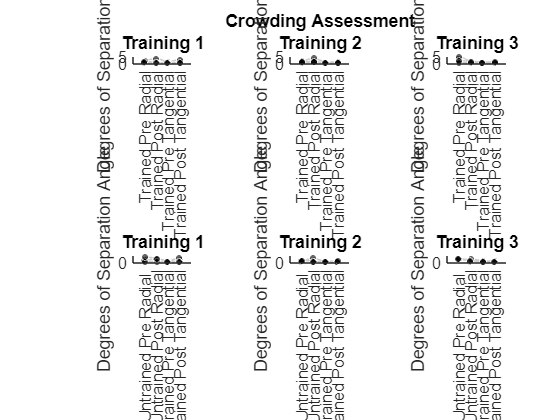

% create label names for each condition of data

condition_names = {'Trained Pre Radial', 'Trained Post Radial','Trained Pre Tangential', 'Trained Post Tangential','Untrained Pre Radial ','Untrained Post Radial','Untrained Pre Tangential', 'Untrained Post Tangential'};
f1 = figure;

% plots are 2 x 3: 3 trained conditions on top, 3 untrained conditions on
% bottom

subplot(2, 3, 1)

% load in pre and post data for each training type (this is repeated in
% every subplot)

CrowdingTrainedTT1(:,1) = cell2mat({DataTableCrowdingTT1{:,2}});
CrowdingTrainedTT1(:,2) = cell2mat({DataTableCrowdingTT1{:,6}});
CrowdingTrainedTT1(:,3) = cell2mat({DataTableCrowdingTT1{:,4}});
CrowdingTrainedTT1(:,4) = cell2mat({DataTableCrowdingTT1{:,8}});

% plot the data as pre vs post, using scatter to present individual datapoints, and using the 'withinlines' tag to show
% individual differences between groups

j1 = daboxplot(CrowdingTrainedTT1,'xtlabels', condition_names(1:4),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('Degrees of Separation Angle')
title([newline 'Training 1'])
ylim([0 6])


subplot(2, 3, 2)
CrowdingTrainedTT2(:,1) = cell2mat({DataTableCrowdingTT2{:,2}});
CrowdingTrainedTT2(:,2) = cell2mat({DataTableCrowdingTT2{:,6}});
CrowdingTrainedTT2(:,3) = cell2mat({DataTableCrowdingTT2{:,4}});
CrowdingTrainedTT2(:,4) = cell2mat({DataTableCrowdingTT2{:,8}});

j2 = daboxplot(CrowdingTrainedTT2,'xtlabels', condition_names(1:4),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('Degrees of Separation Angle')
title(['Crowding Assessment' newline 'Training 2'])
ylim([0 6])

subplot(2, 3, 3)
CrowdingTrainedTT3(:,1) = cell2mat({DataTableCrowdingTT3{:,2}});
CrowdingTrainedTT3(:,2) = cell2mat({DataTableCrowdingTT3{:,6}});
CrowdingTrainedTT3(:,3) = cell2mat({DataTableCrowdingTT3{:,4}});
CrowdingTrainedTT3(:,4) = cell2mat({DataTableCrowdingTT3{:,8}});


j3 = daboxplot(CrowdingTrainedTT3,'xtlabels', condition_names(1:4),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('Degrees of Separation Angle')
title([newline 'Training 3'])
ylim([0 6])

subplot(2, 3, 4)

CrowdingUntrainedTT1(:,1) = cell2mat({DataTableCrowdingTT1{:,3}});
CrowdingUntrainedTT1(:,2) = cell2mat({DataTableCrowdingTT1{:,7}});
CrowdingUntrainedTT1(:,3) = cell2mat({DataTableCrowdingTT1{:,5}});
CrowdingUntrainedTT1(:,4) = cell2mat({DataTableCrowdingTT1{:,9}});


j4 = daboxplot(CrowdingUntrainedTT1,'xtlabels', condition_names(5:8),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('Degrees of Separation Angle')
title([newline 'Training 1'])
ylim([0 6])


subplot(2, 3, 5)
CrowdingUntrainedTT2(:,1) = cell2mat({DataTableCrowdingTT2{:,3}});
CrowdingUntrainedTT2(:,2) = cell2mat({DataTableCrowdingTT2{:,7}});
CrowdingUntrainedTT2(:,3) = cell2mat({DataTableCrowdingTT2{:,5}});
CrowdingUntrainedTT2(:,4) = cell2mat({DataTableCrowdingTT2{:,9}});

j5 = daboxplot(CrowdingUntrainedTT2,'xtlabels', condition_names(5:8),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('Degrees of Separation Angle')
title([newline 'Training 2'])
ylim([0 6])


subplot(2, 3, 6)
CrowdingUntrainedTT3(:,1) = cell2mat({DataTableCrowdingTT3{:,3}});
CrowdingUntrainedTT3(:,2) = cell2mat({DataTableCrowdingTT3{:,7}});
CrowdingUntrainedTT3(:,3) = cell2mat({DataTableCrowdingTT3{:,5}});
CrowdingUntrainedTT3(:,4) = cell2mat({DataTableCrowdingTT3{:,9}});


j6 = daboxplot(CrowdingUntrainedTT3,'xtlabels', condition_names(5:8),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('Degrees of Separation Angle')
title([newline 'Training 3'])
ylim([0 6])


% As a note, you probabably want to pop these out in a new window for
% better viewing.

columnNames =  {'Subject ID', 'Trained Pre Radial', 'Trained Post Radial','Trained Pre Tangential', 'Trained Post Tangential','Untrained Pre Radial ','Untrained Post Radial','Untrained Pre Tangential', 'Untrained Post Tangential','Training Type'};
DataTableCrowding_table = cell2table(DataTableCrowding,'VariableNames',columnNames);
writetable(DataTableCrowding_table, [SubjectDirectory 'DataTableCrowding.csv']);